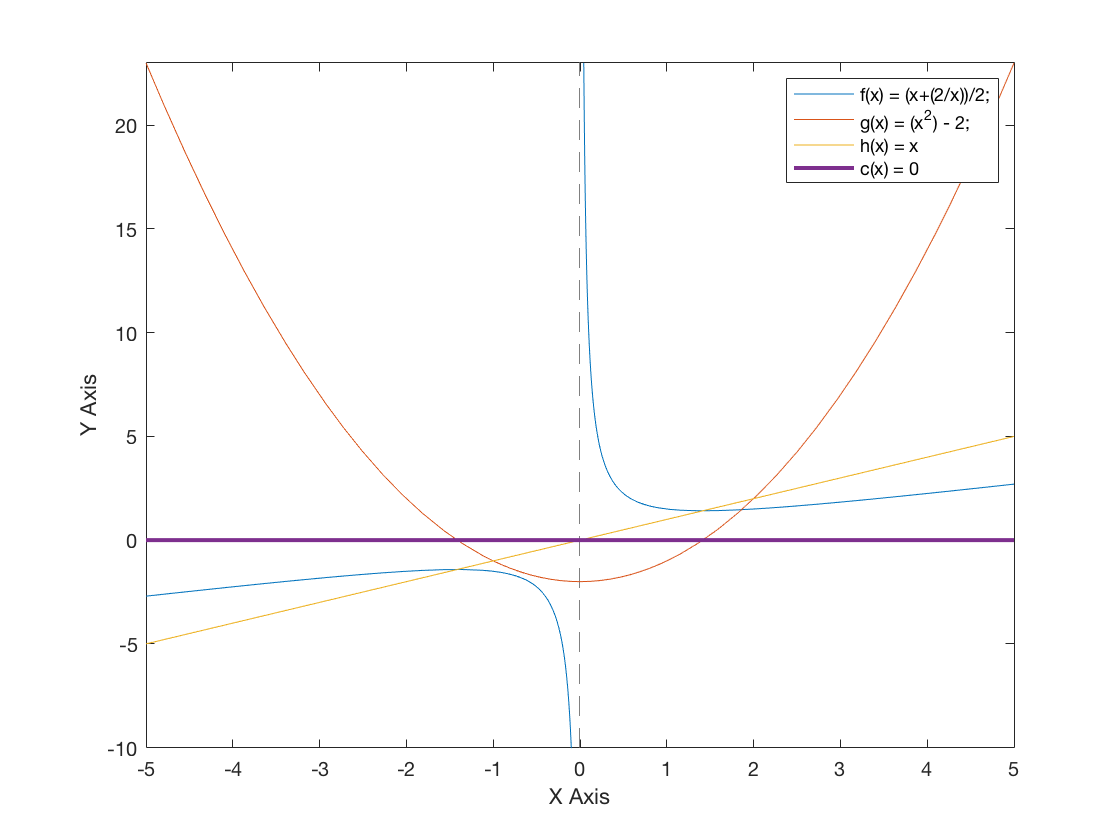

% Number (a).i
f = @(x) (x+(2./x))./2;
g = @(x) (x.^2) - 2;
h = @(x) x;
c = 0;
%The root of these two functions are the same
%We see an intersection at x = 2

fplot(f);
hold on;
fplot(g);
fplot(h);
fplot(c,'LineWidth',2)
hold off;

xlabel('X Axis');
ylabel('Y Axis');
legend('f(x) = (x+(2/x))/2;','g(x) = (x^2) - 2;','h(x) = x','c(x) = 0');


% Number (a).ii
% p0 will be + or - depening if p0 is + or -
% The more iterations, the more accurate it will be
fp(f, 1, 30)

We are on iteration:6


p = 1.4142

ans = 1.4142

% fp(f, -1, 30)

%Number (a).iii


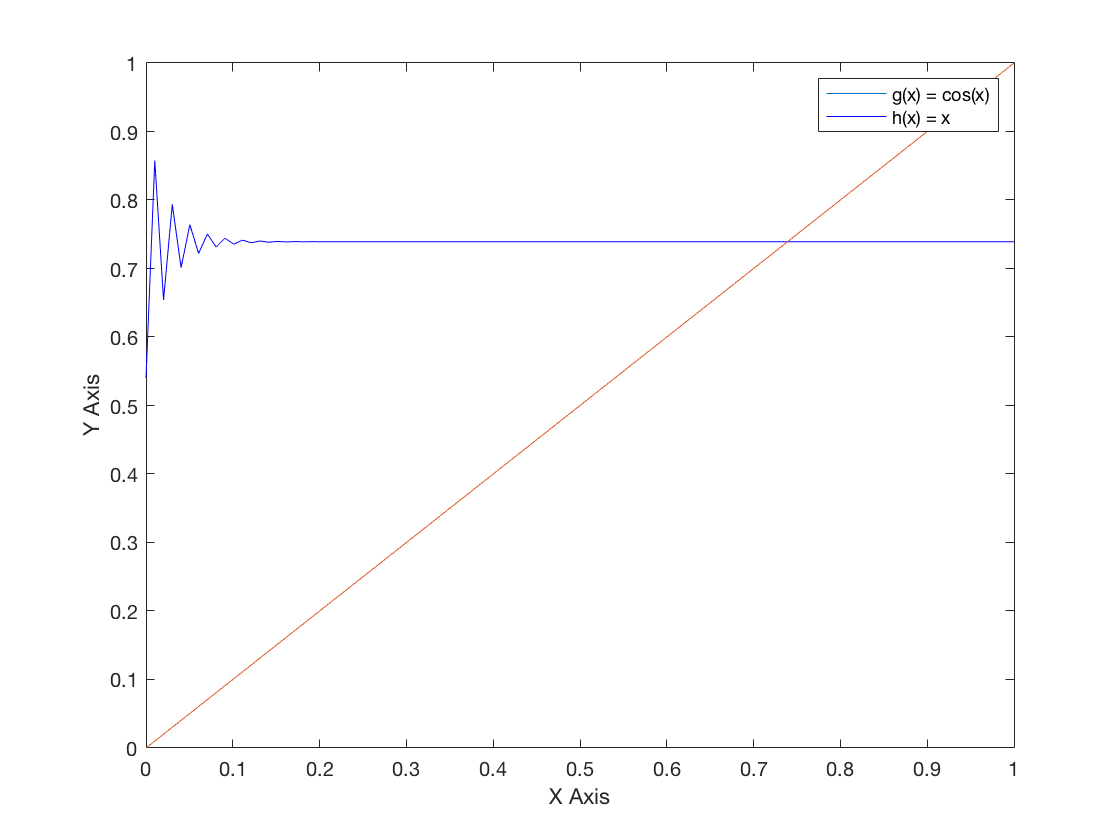

%Number (b).i
g = @(x) cos(x);
h = @(x) x;
x = linspace(0,1,100);
y = linspace(0,1,100);
xP = gPlot(g,1,100);
yP = gPlot(g,1,100);

plot(x,xP,y,yP,'b')
hold on 
plot(x,h(x))
hold off

xlabel('X Axis');
ylabel('Y Axis');
legend('g(x) = cos(x)', 'h(x) = x');

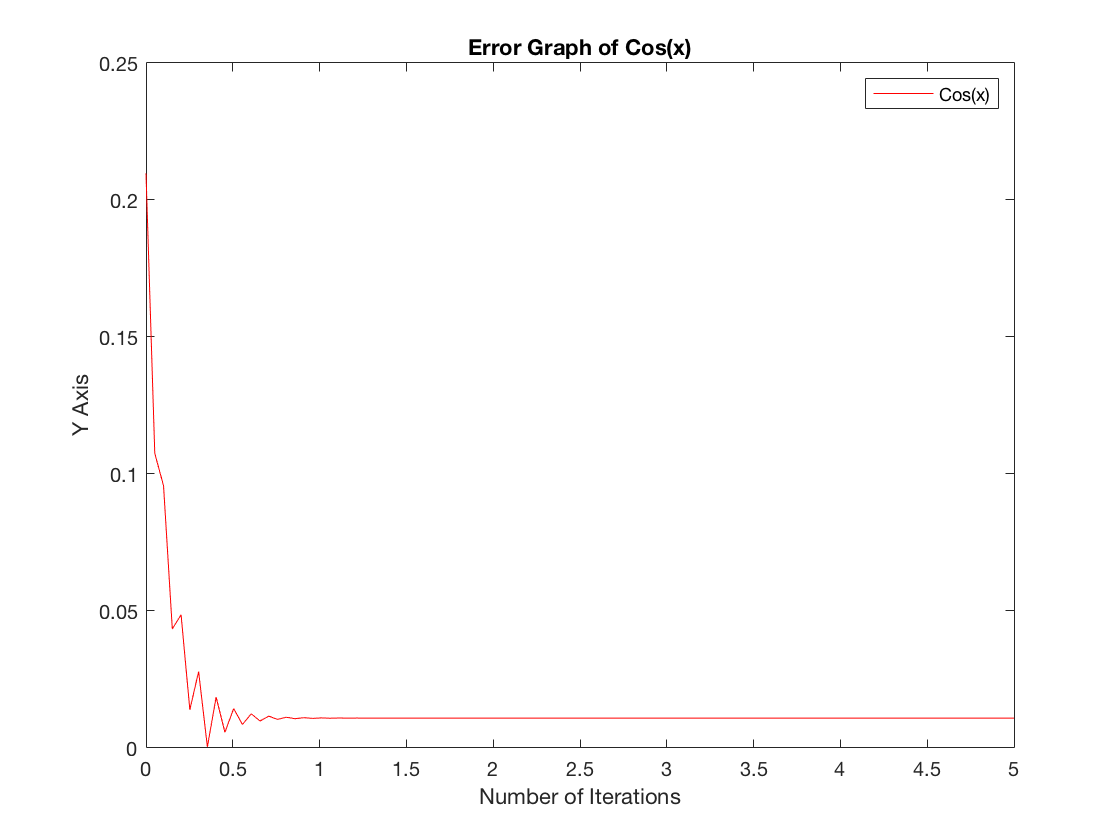


%Number (b).ii
xError = linspace(0,5,100);
yError = abs(.75-xP);
plot(xError,yError,'r');

title('Error Graph of Cos(x)');
legend('Cos(x)');
xlabel('Number of Iterations');
ylabel('Y Axis');

%Number (c).i
clear
g = @(x) 2*x;
fp(g,0,5)

We are on iteration:1


p = 0

ans = 0

% To converge to 0, we need p0 to be 0 or near 0.
% Any other value will make it + or - Inf.


function p = fp(f, p0, maxits)
    i = 1;
    while (i <= maxits)
        p = f(p0);
        if(abs(p-p0) < eps())
           fprintf("We are on iteration:" + i + "\n");
           break;
        end
        i = i+1;
        p0 = p;  
    end
    p = p0;
end

function p_plot = gPlot(g, p0, maxits)
vec = zeros(1,maxits);
temp=0;
for i=1:maxits
    x=temp;
    temp= g(p0);
    p0=temp;
    vec(i) = p0; 
end
p_plot=vec;
end
